clearvars -except cs300;
close all;
load E:\Data\result\grid\grid300_CSR.mat;
num=60;lmax=60;
cs=gmt_grid2cs(grid300_CSR(:,:,1:num),lmax);
for ii=1:num
    temp(:,:)=cs(ii,:,:);
    cs300(ii,:,:)=gmt_mc2gc(temp);
end
% save cs300.mat cs300

sc=gmt_cs2sc(reshape(cs300(8,:,:),lmax+1,lmax+1));sc(sc==0)=NaN;
m1=-60:60;l1=0:60;
[m,l]=meshgrid(m1,l1);

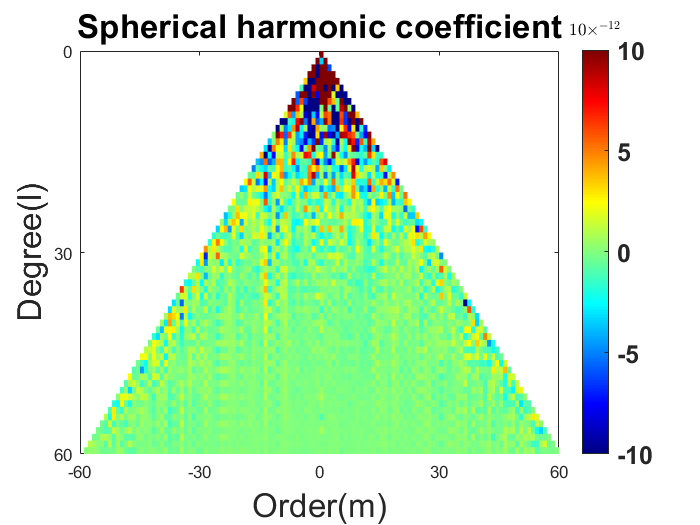

figure(1)
pcolor(m,l,sc./1e-12);shading flat;
caxis([-10,10]);colormap('jet');grid off;
xlabel('Order(m)','Fontname','Time New Roman',"FontSize",20);
ylabel('Degree(l)','Fontname','Time New Roman',"FontSize",20);
set(gca, 'YDir', 'reverse')
xticks([-60,-30,0,30,60]);yticks([0,30,60]);
title('Spherical harmonic coefficient','FontName','Time New Roman','Fontsize',20,'fontweight','bold')
h=colorbar('v','FontSize',15,'fontweight','bold');
set(get(h,'title'),'string','$10\times^{-12}$', 'Interpreter', 'latex','FontSize',10,'fontweight','bold');